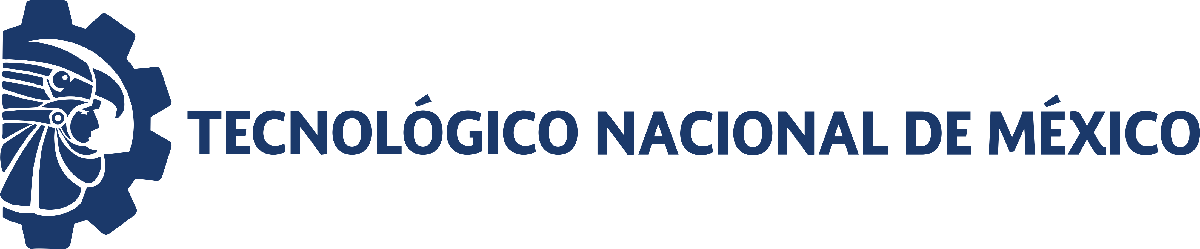                                 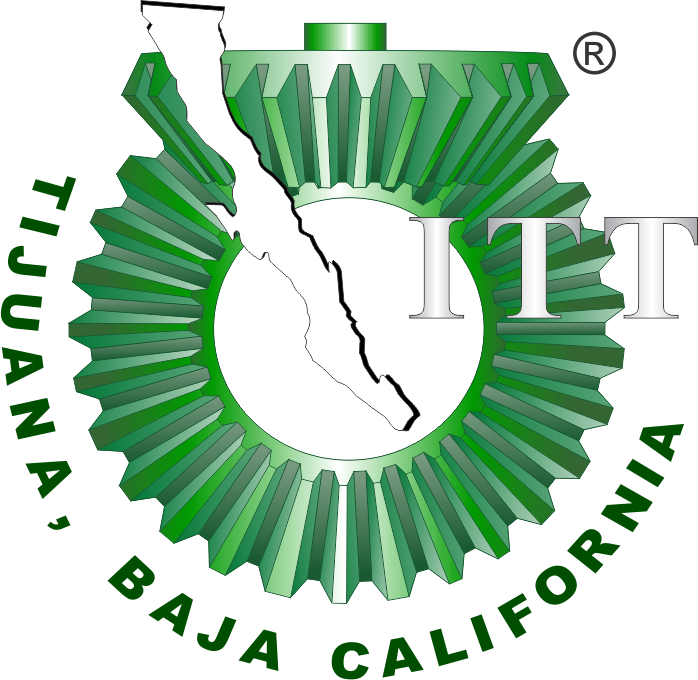

# Práctica 2: Modelo y control del sistema cardiovascular mediante el modelo Windkessel

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

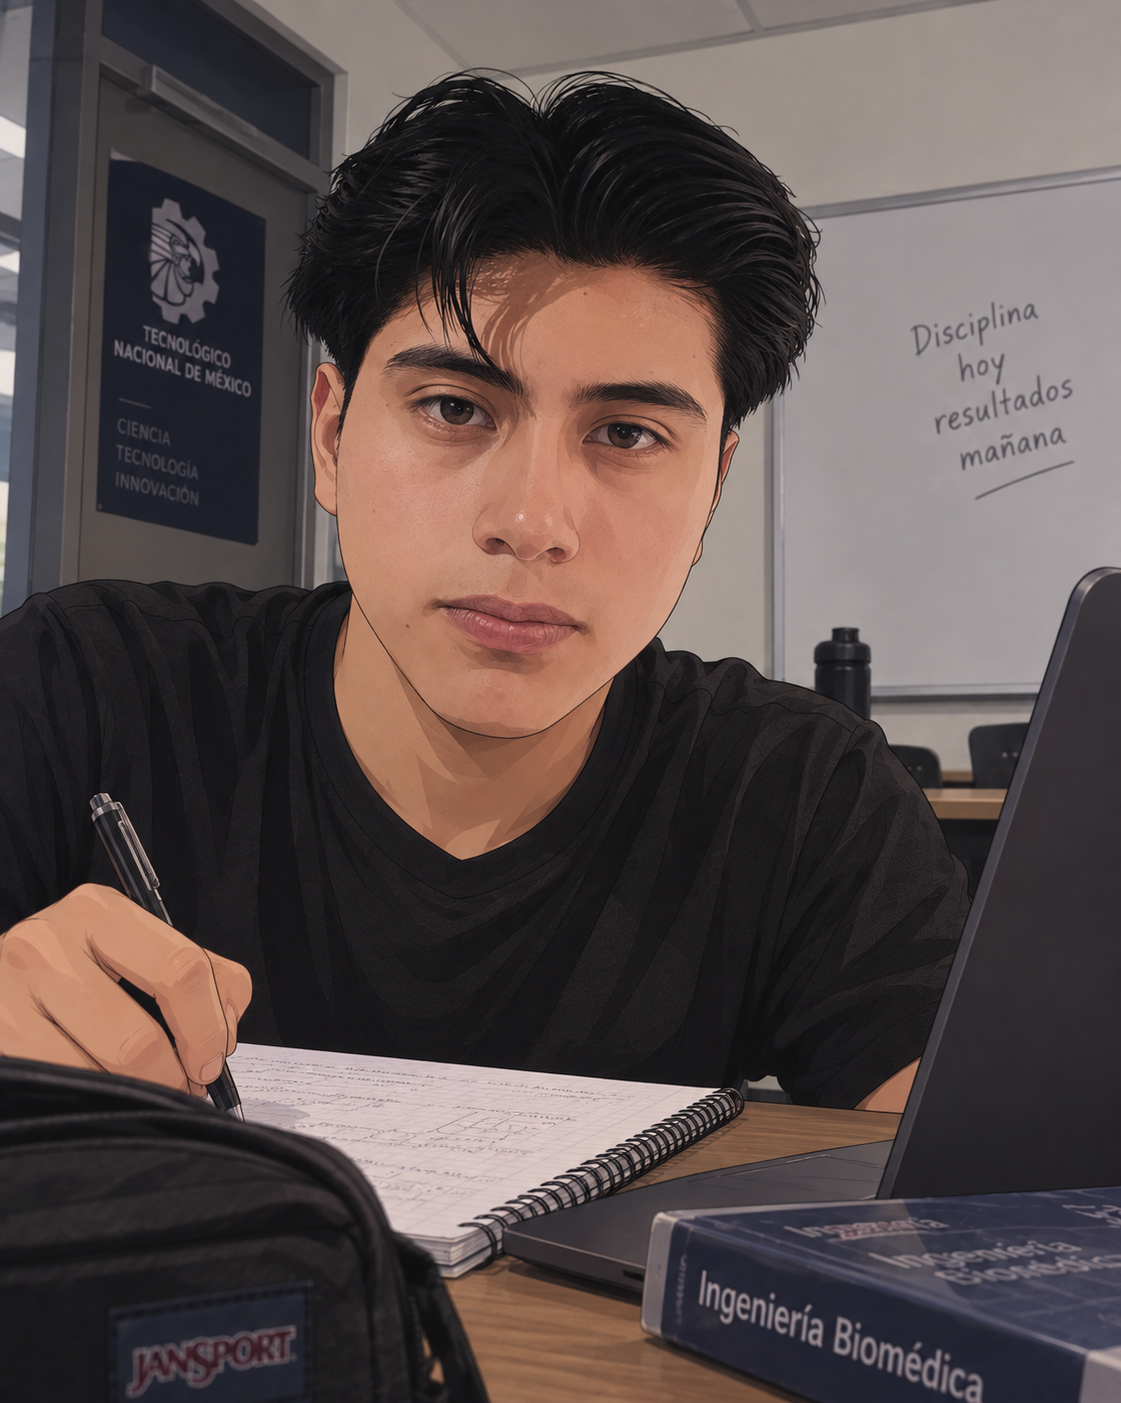

Nombre del alumno: Bautista Paz Jesus Geovanny

Número de control: 23212181

Correo institucional: l23212181**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistemap2')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistemap2',parameters);

t_data = (0:0.1:15)';
t = (0:0.001:15)';
Pa = interp1(t_data, x.Pa, t,'previous')

Pa =     0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420


writematrix(Pa,'signal.xlsx')

## Respuesta: Individuos

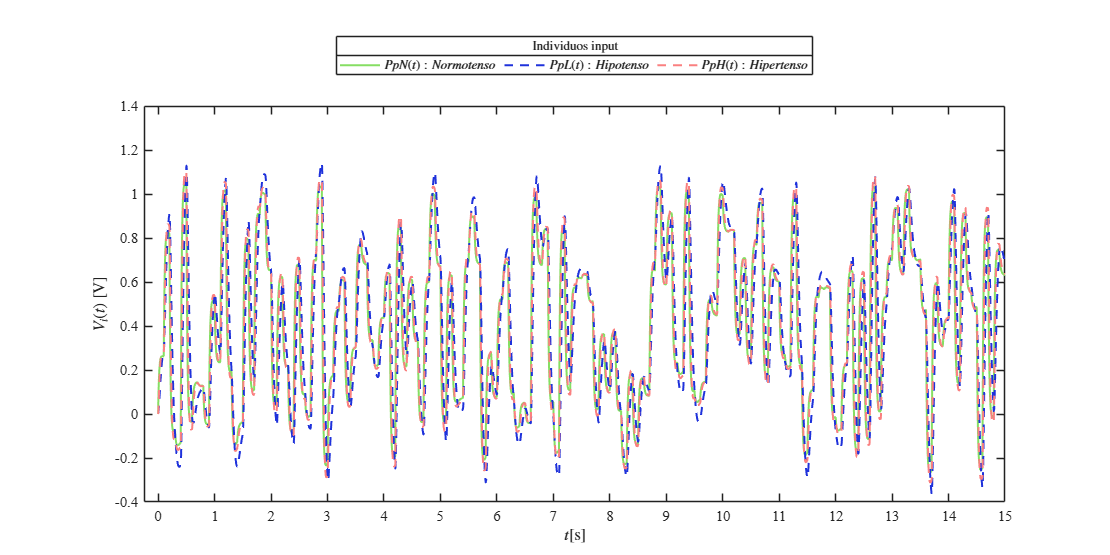

plotsignals(x.t,x.PpN,x.PpL,x.PpH,'Individuos')

## Respuesta: hipotenso

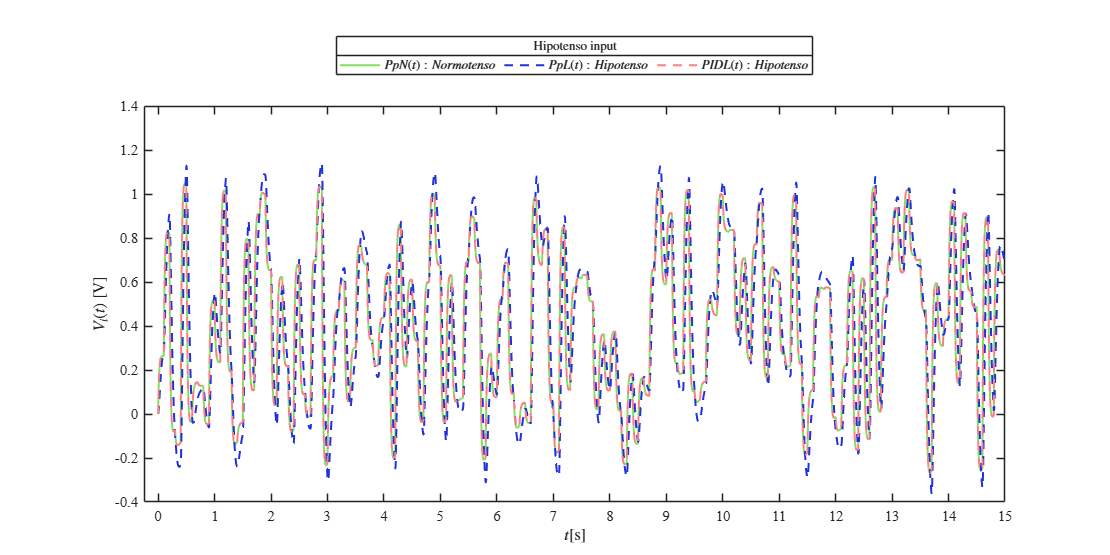

plotsignals(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Respuesta: hipertenso

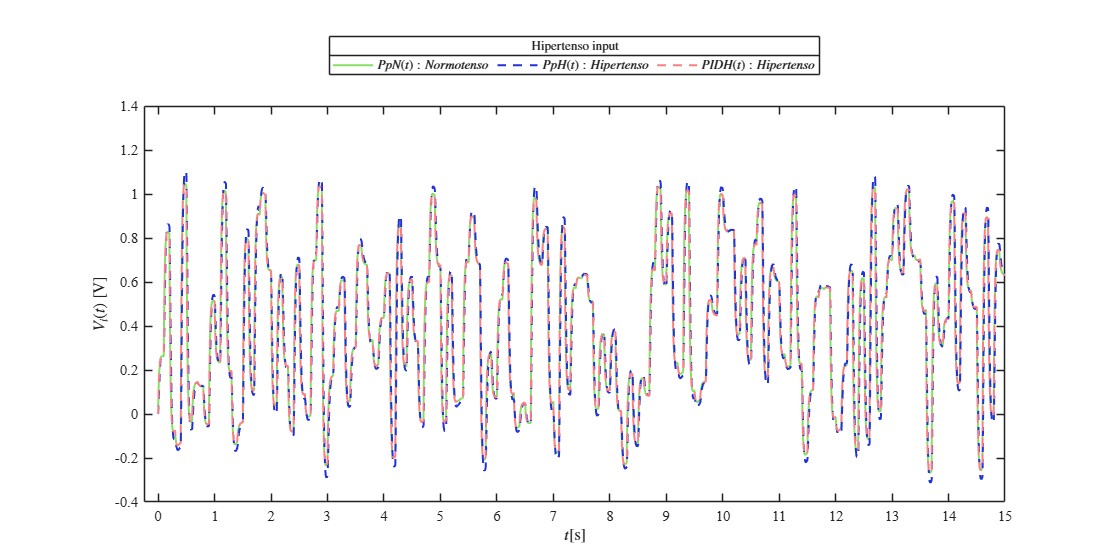

plotsignals(x.t,x.PpN,x.PpH,x.PIDH,'Hipertenso')

## Modelo de EDOs

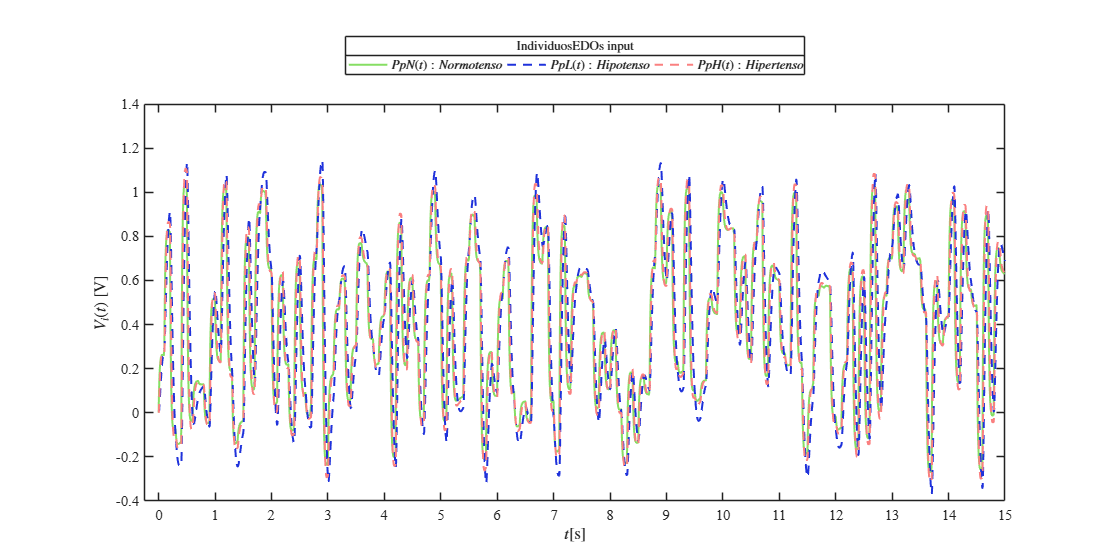

par_hipo = [0.010,0.001,1,3.5];
par_normo = [0.010,0.001,1,1.5];
par_hiper = [0.010,0.001,1,1];
PpN = cardio(par_normo,Pa,t);
PpL = cardio(par_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotsignals(t,PpN,PpL,PpH,'IndividuosEDOs')


function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4);
    dt = t(2);
    n = round(t(end)/dt);

    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;

    for i = 1:n
        FL(i+1) = FL(i) + (-(1/L)*Pp(i) + (1/L)*Pa(i))*dt;
        Pp(i+1) = Pp(i) + ((1/C)*FL(i) - (1/(Z*C) + 1/(R*C))*Pp(i) + 1/(Z*C)*Pa(i))*dt;
    end
end

## Funcion: Respuestas de la simulacion

function plotsignals (t,Pp1,Pp2,Pp3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,12,6])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [118, 196, 87]/225;
    clr2 = [27, 44, 193]/225;
    clr3 = [221, 113, 113]/225;
    order = [clr1;clr2;clr3]; colororder(order)

    if signal == "Individuos"
        plot(t,Pp1,'-',t,Pp2,'--',t,Pp3,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('$PpN(t): Normotenso$','$PpL(t): Hipotenso$','$PpH(t): Hipertenso$');
    elseif signal == "Hipotenso"
        plot(t,Pp1,'-',t,Pp2,'--',t,Pp3,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('$PpN(t): Normotenso$','$PpL(t): Hipotenso$','$PIDL(t): Hipotenso$');
    elseif signal == "Hipertenso"
        plot(t,Pp1,'-',t,Pp2,'--',t,Pp3,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('$PpN(t): Normotenso$','$PpH(t): Hipertenso$','$PIDH(t): Hipertenso$');
    elseif signal == "IndividuosEDOs"
        plot(t,Pp1,'-',t,Pp2,'--',t,Pp3,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('$PpN(t): Normotenso$','$PpL(t): Hipotenso$','$PpH(t): Hipertenso$');
    end
   
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    title(L,[signal,' input'])

    xlabel('$t$[s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')

    xlim([-0.25 15]); xticks(0:1:15)
    ylim([-0.4 1.4]); yticks(-0.4:0.2:1.4)
   
  
exportgraphics(gcf,[signal,'_matlab2.pdf'],'contenttype','vector')
end